data_strct = フィールドをもつ struct :
    clean: [1×1 struct]


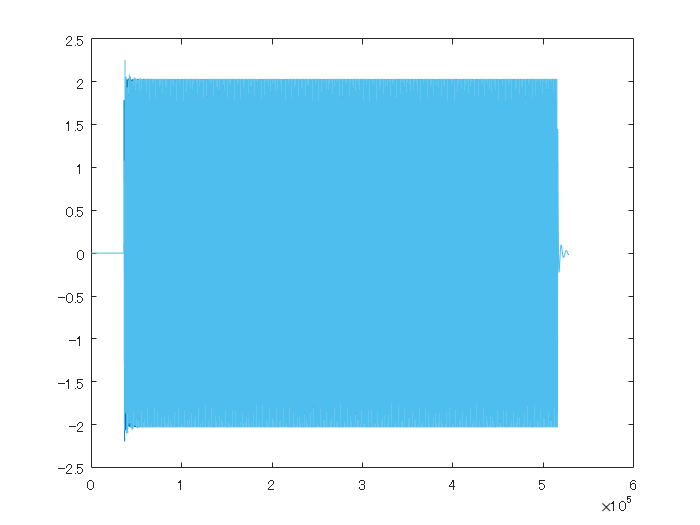

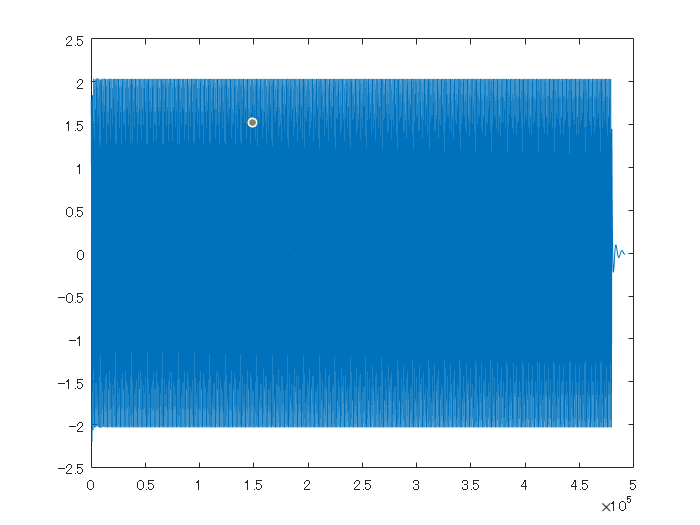

ans =     0.0001
    0.0000
    0.0001
    0.0001
    0.0000
    0.0001
    0.0000
    0.0002
    0.0001
    0.0002


clear all

### データベースの読み込み

AMP_TYPE = "a";
SUPPLY_TYPE = "clean";
DATA_PATH  = "./data/processed/";
data_strct = load(DATA_PATH +"amp_"+AMP_TYPE+"/"+SUPPLY_TYPE+".mat")

### 解析データの取得

%解析するデータの指定
poly_type = "aa";
freq_type = 1;
vpp_type = 1;
trial_type = 1;

%読み込み
signal = data_strct.(SUPPLY_TYPE).(poly_type).freq(freq_type).vpp(vpp_type).trial(trial_type).signal;
plot(signal)

### データの切り抜き処理

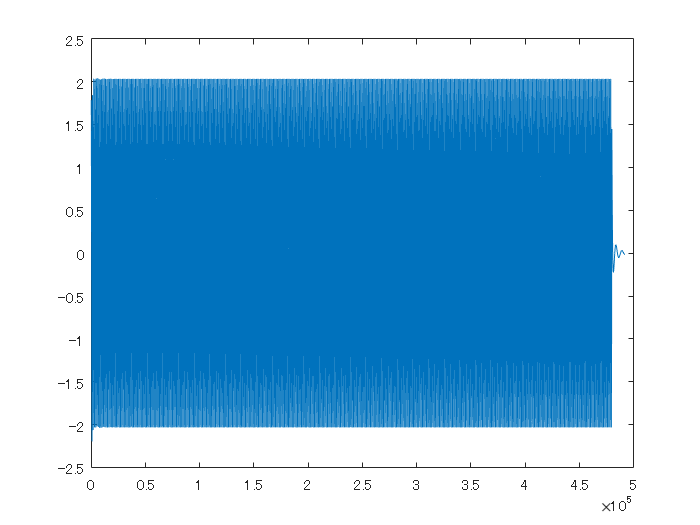

n = 1;
signaln = signal(:,n);

for i=1:length(signaln)
    if abs(signaln(i)) > max(signaln)*0.7
        start = i;
        break
    end
end

plot(signaln(start:end))